### **Kidney Stone Detection using Image Processing**

**Group: C2_Group 5**

**Group Members:**

- 200021348 - Fardun Islam Aumio

- 200021350 - Sserujja Abdallah Kulumba

- 200021354 - Pushpita Khan

- 200021358 - Afia Tahsin Chowdhury

- 190021240 - Mohamed Gibreile

clc;
clear all;
close all;
warning off;

**Prompt user to select an image file**

[imageFile, imagePath] = uigetfile({'*.png;*.jpg;*.jpeg', 'Kidney Images (*.png, *.jpg, *.jpeg)'});
if isequal(imageFile, 0)
    disp('No file selected.');
    return;
end
imageFile = fullfile(imagePath, imageFile);

**Load and display the image**

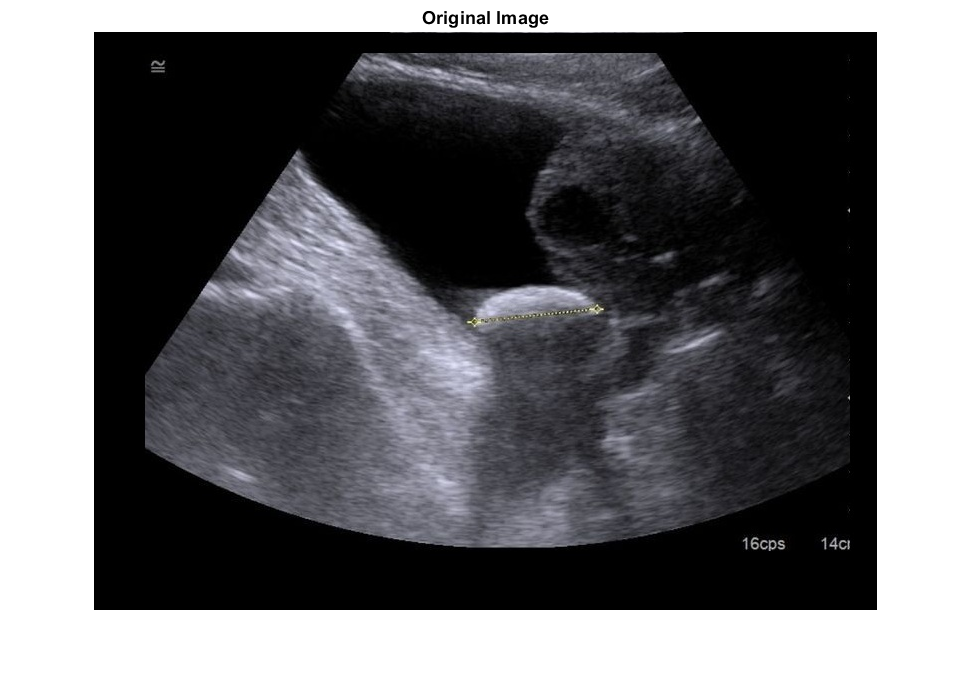

originalImage = imread(imageFile);
figure, imshow(originalImage), title('Original Image');

**Convert to grayscale**

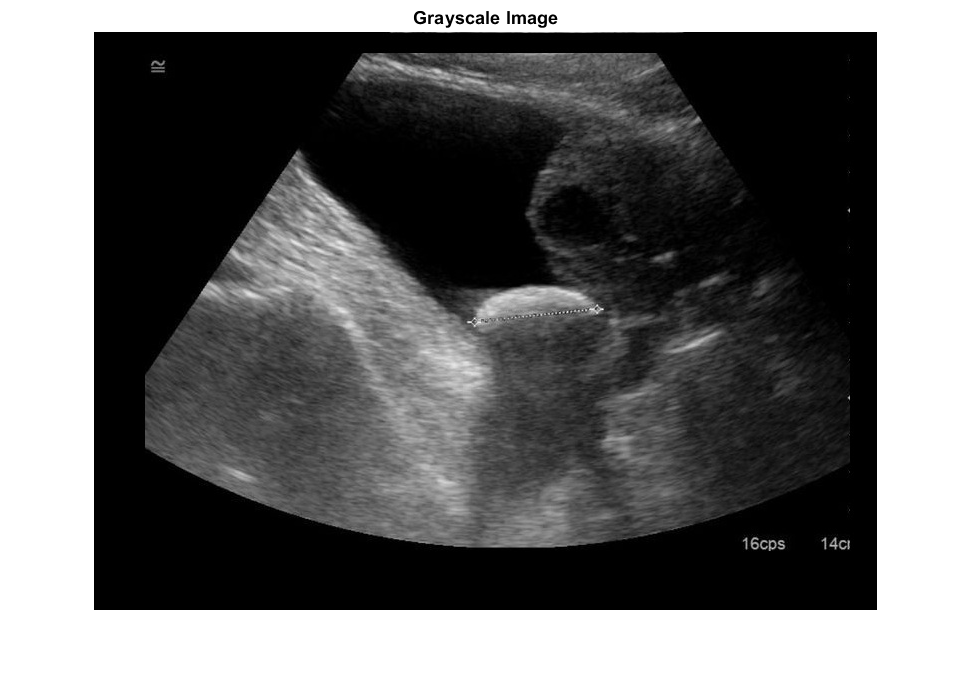

if size(originalImage, 3) == 3 % this checks whether its RGB or not
    grayscaleImage = rgb2gray(originalImage);
else
    grayscaleImage = originalImage;
end
figure, imshow(grayscaleImage), title('Grayscale Image');

**Apply median filtering to reduce noise**

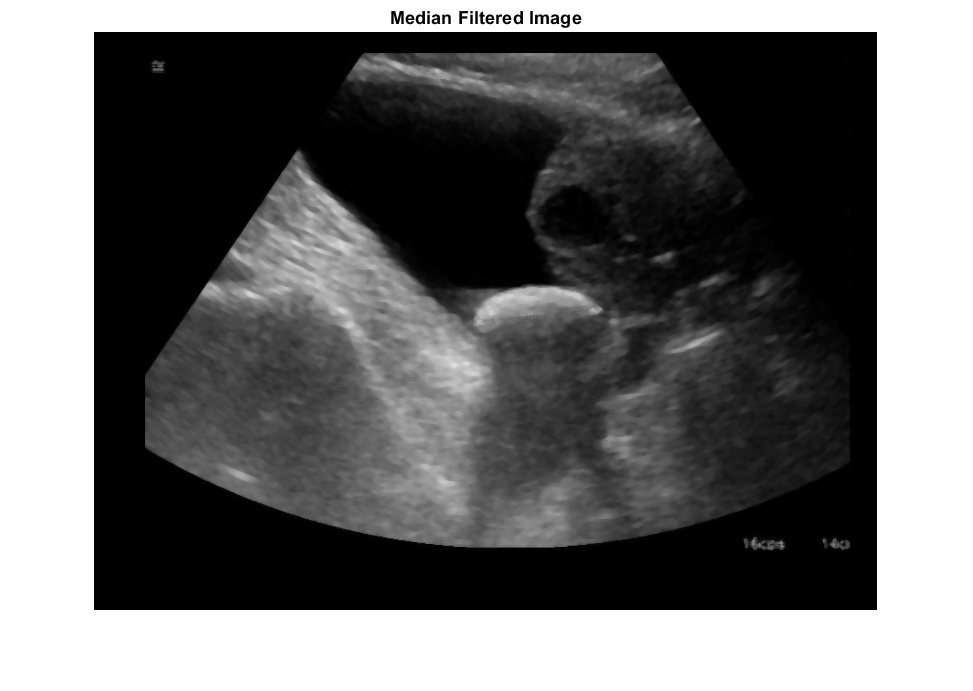

filteredGrayImage = medfilt2(grayscaleImage, [5 5]);
figure, imshow(filteredGrayImage), title('Median Filtered Image');

**Apply adaptive thresholding with adjusted sensitivity**

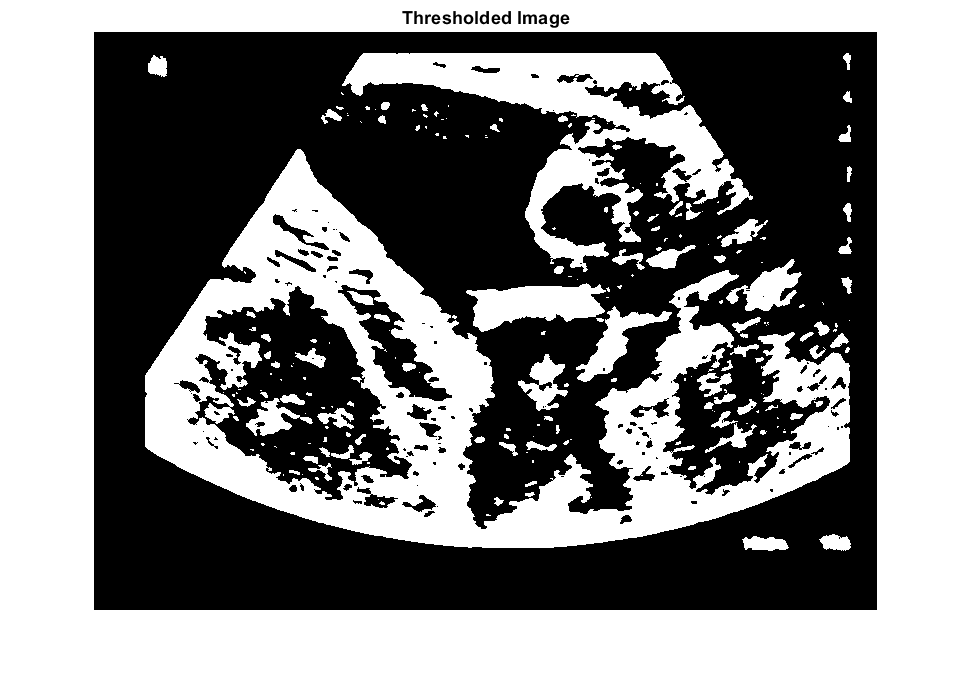

binaryImage = imbinarize(filteredGrayImage, 'adaptive', 'ForegroundPolarity', 'bright', 'Sensitivity', 0.6);
figure, imshow(binaryImage), title('Thresholded Image');

**Perform morphological operations to fill holes and remove small artifacts**

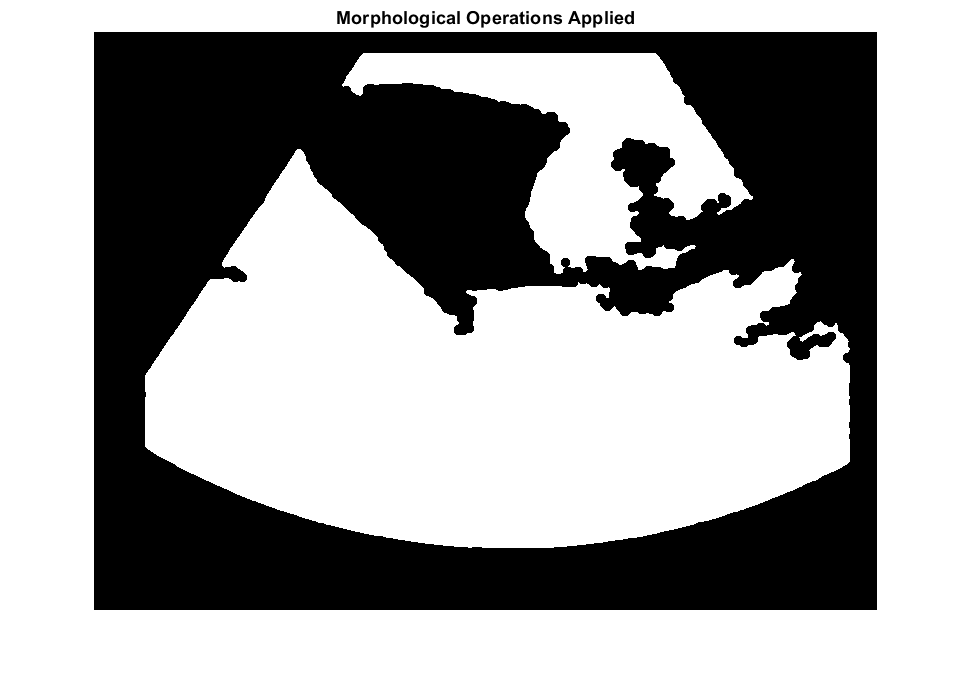

se = strel('disk', 5); % Increase structuring element size
morphedImage = imclose(binaryImage, se);
morphedImage = imfill(morphedImage, 'holes');
morphedImage = bwareaopen(morphedImage, 1500); % Increased area threshold
figure, imshow(morphedImage), title('Morphological Operations Applied');

**Apply mask to original image**

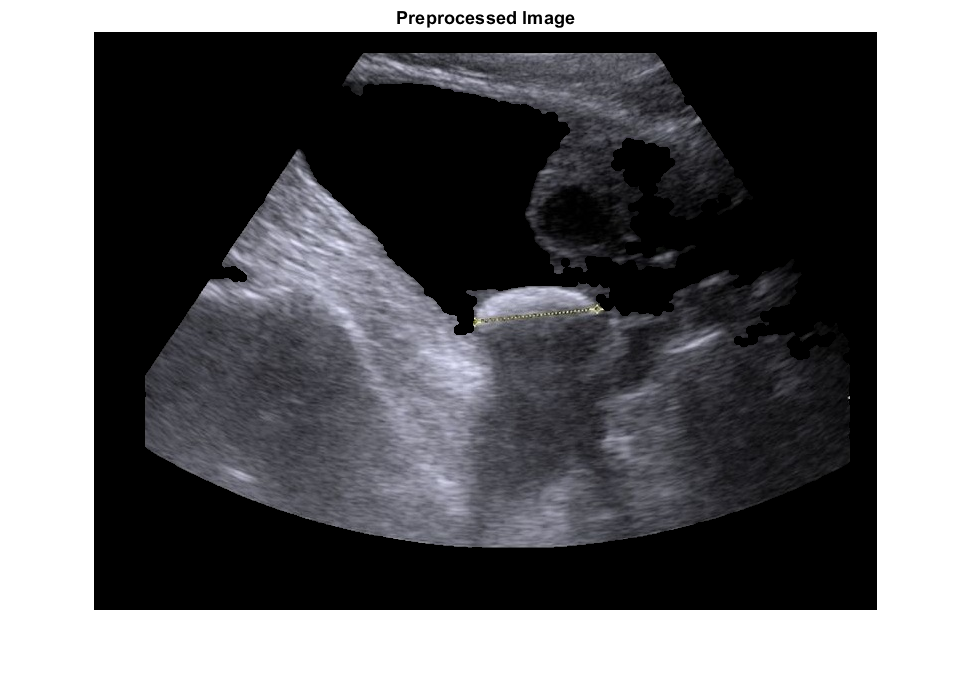

processedImage = uint8(double(originalImage) .* repmat(morphedImage, [1 1 3]));
figure, imshow(processedImage), title('Preprocessed Image');

**Adjust image contrast**

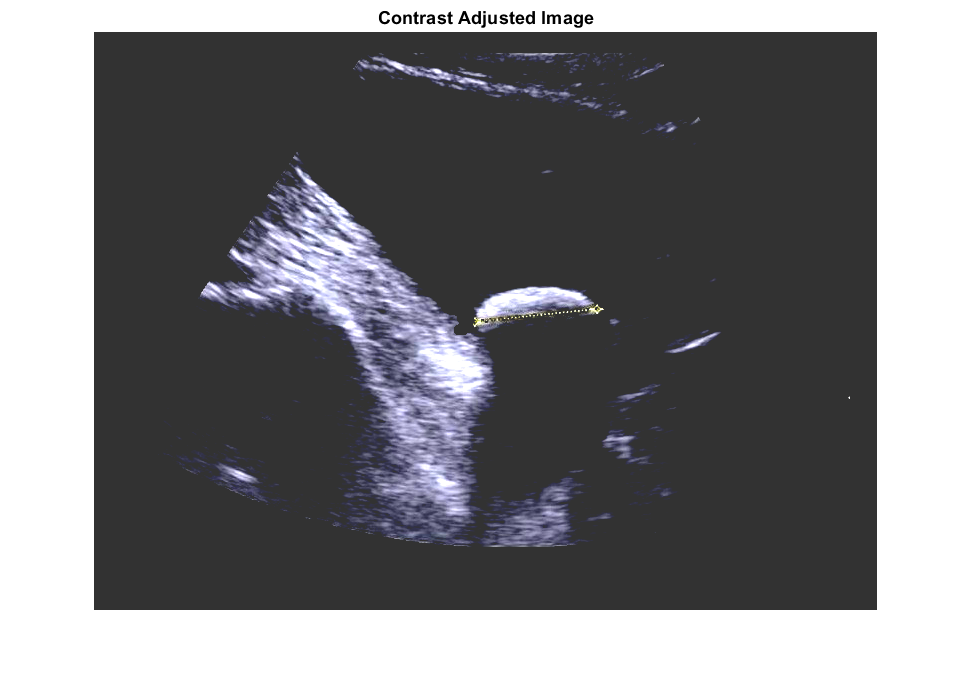

adjustedImage = imadjust(processedImage, [0.4 0.8], []) + 50;
figure, imshow(adjustedImage), title('Contrast Adjusted Image');

**Convert to grayscale again**

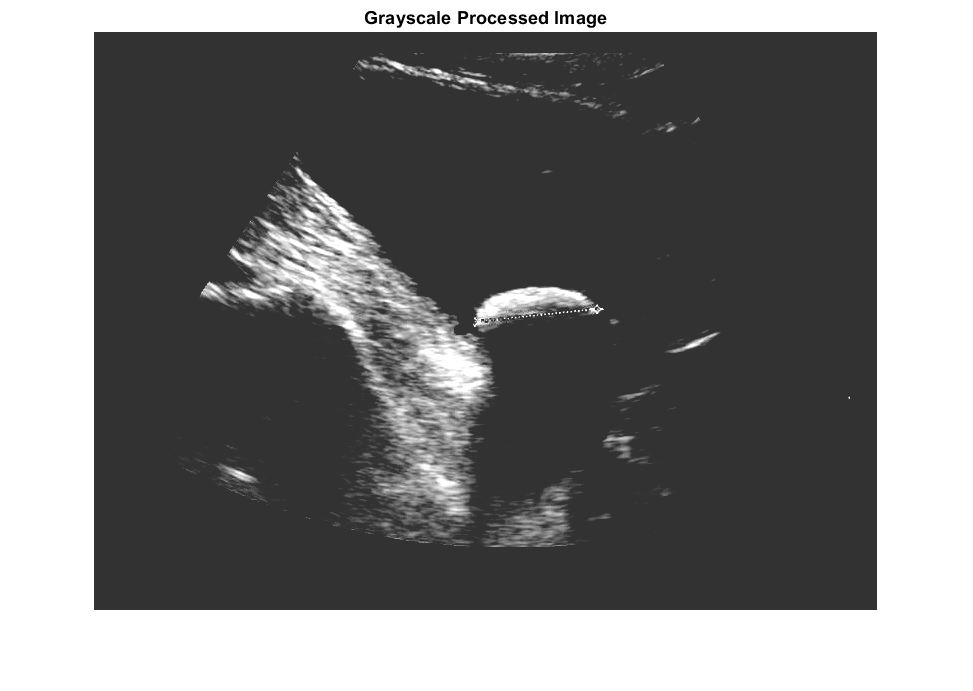

grayProcessedImage = rgb2gray(adjustedImage);
figure, imshow(grayProcessedImage); title('Grayscale Processed Image');

**Thresholding for stone detection with refined intensity**

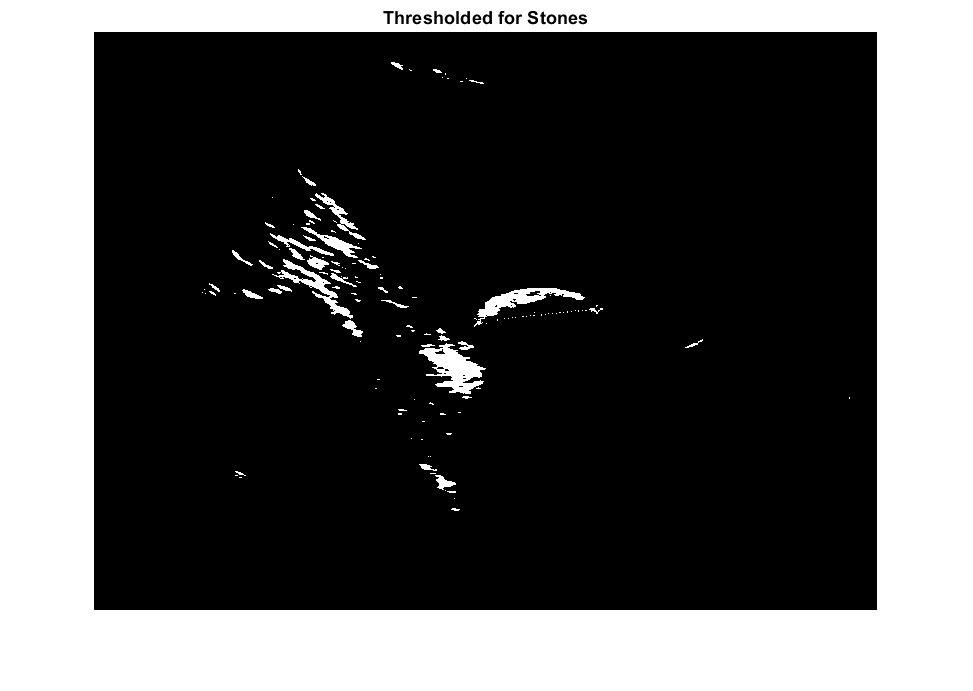

stoneRegions = grayProcessedImage > 220; % Adjusted intensity threshold
figure, imshow(stoneRegions), title('Thresholded for Stones');

**Define ROI**

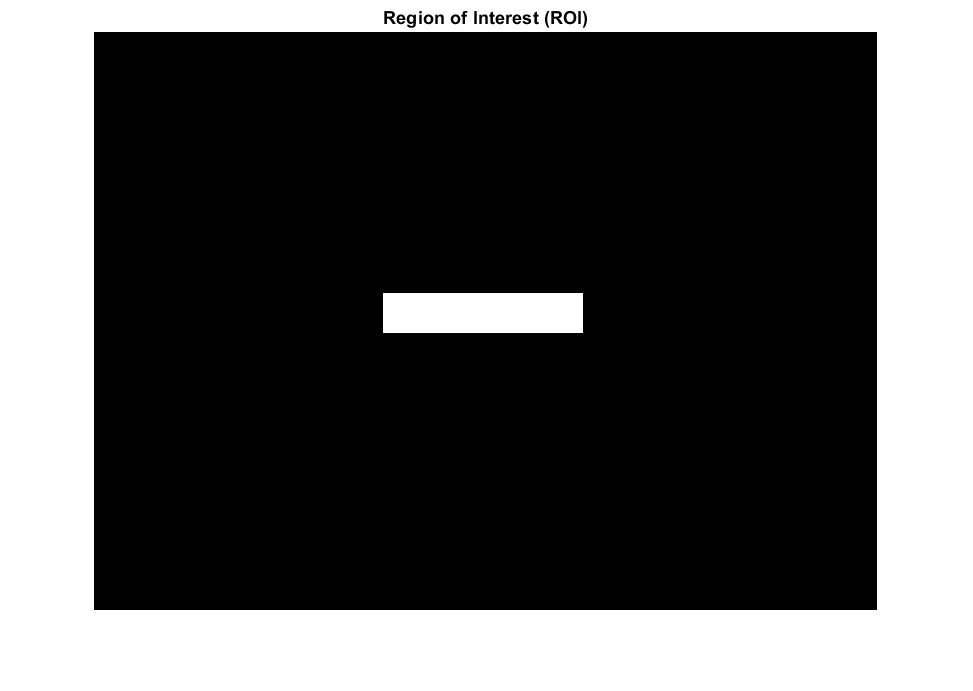

[imageRows, imageCols] = size(stoneRegions);
xCenter = imageRows / 2;
yCenter = imageCols / 3;
rowPoints = [xCenter xCenter+200 xCenter+200 xCenter];
colPoints = [yCenter yCenter yCenter+40 yCenter+40];
roiMask = roipoly(stoneRegions, rowPoints, colPoints);
figure, imshow(roiMask), title('Region of Interest (ROI)');

** Apply ROI mask**

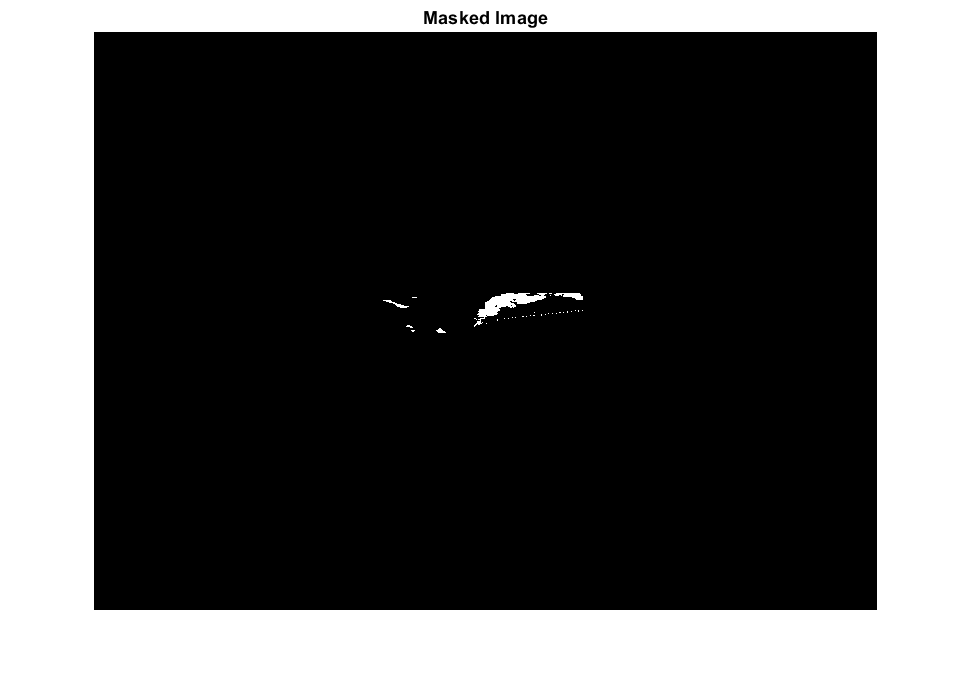

maskedImage = stoneRegions .* double(roiMask);
figure, imshow(maskedImage), title('Masked Image');

**Remove small objects with increased threshold**

finalSegmentedImage = bwareaopen(maskedImage, 10);

**Count connected components**

[labeledImage, numRegions] = bwlabel(finalSegmentedImage);

**Compute region properties**

stats = regionprops(labeledImage, grayscaleImage, 'BoundingBox','Area', 'Centroid', 'MeanIntensity');
% Convert stats to table format for displaying metrics
if ~isempty(stats)
    metrics = struct2table(stats, 'AsArray', true);
else
    metrics = table([], [], [], 'VariableNames', {'Area', 'Centroid', 'MeanIntensity'});
end
disp(metrics);

    Area        Centroid                  BoundingBox               MeanIntensity
    ____    ________________    ________________________________    _____________

     57     303.18    272.77    289.5    268.5       26        8       179.82    
     12        316       295    312.5    293.5        7        3       174.08    
     29     347.21    299.55    342.5    296.5       10        5       182.59    
    767     412.81    271.92    380.5    261.5       73       34       188.75    
    118     477.81    264.18    460.5    261.5       29        7       192.69    



% Create processed image for display
processedImage = uint8(double(originalImage) .* repmat(finalSegmentedImage, [1 1 size(originalImage, 3)]));

**Draw bounding boxes around detected stones**

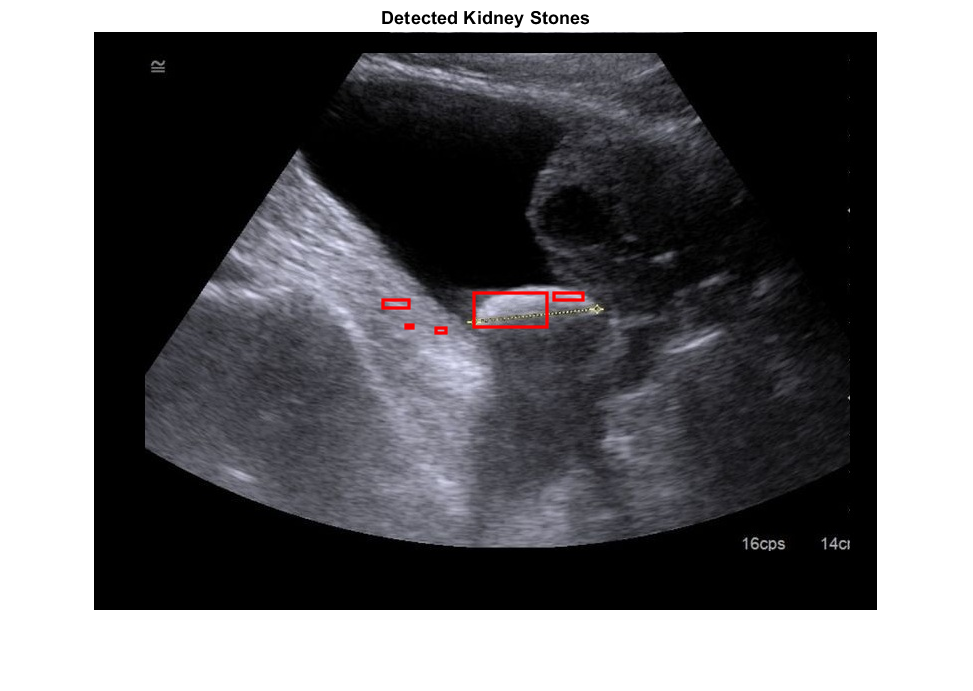

figure, imshow(originalImage), title('Detected Kidney Stones'); hold on;
stats = regionprops(labeledImage, 'BoundingBox');
for k = 1:length(stats)
    rectangle('Position', stats(k).BoundingBox, 'EdgeColor', 'r', 'LineWidth', 2);
end
hold off;

**Display detection result**

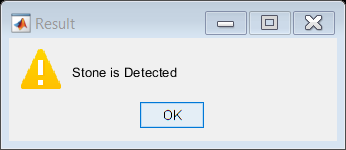

if numRegions >= 1
    msgbox('Stone is Detected', 'Result', 'warn');
else
    msgbox('No Stone is detected', 'Result', 'help');
end